# Holografia binaria

clear;

% Tamano de la pantalla
% Medidas de un Holoeye PlutoVIS
% Ux=0.5 * 15.36E-3;  
% Uy=0.5 * 8.64E-3;  
% Hsize = 1920;
% Vsize = 1080;


Ux = 0.0254/2;    
Uy = 0.0254/2;    
Hsize = 300;
Vsize = 300;

% Coordenadas
xs = Ux*(2/Hsize)*(-Hsize/2:Hsize/2-1);
ys = Uy*(2/Vsize)*(-Vsize/2:Vsize/2-1);
[Xs,Ys] = meshgrid(xs,ys);

## Campo

Vamos a definir el campo $U$ en el plano $z=0$.

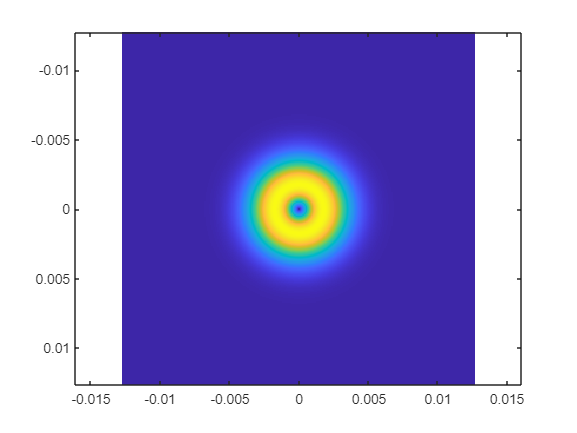

llambd = 633E-9;
w0 = 2.5E-3;

% \vec{k} = (kx,ky,kz)
gamm = pi/3000;     % angle respect z
thxy = pi/4;        % angle in the xy plane, with respect x axis
k = 2*pi/llambd;
kxy = k*sin(gamm);
kx = kxy*cos(thxy);
ky = kxy*sin(thxy);
LG = @(x,y,w0,phi,ll) ((sqrt(x.^2+y.^2)/w0).^abs(ll)) .* exp((-x.^2 - y.^2)/(w0^2)) .* exp(1i*ll*atan2(y,x));

% Modo estructurado
l = 1;
LG = exp(1i*(kx*Xs + ky*Ys)) .* LG(Xs, Ys, w0, 0.0, l);
coeff = sum(abs(LG(:)).^2);
U = LG./sqrt(coeff);

% Visualizacion
imagesc(Xs(1,:),Ys(:,1),abs(U)), axis equal;

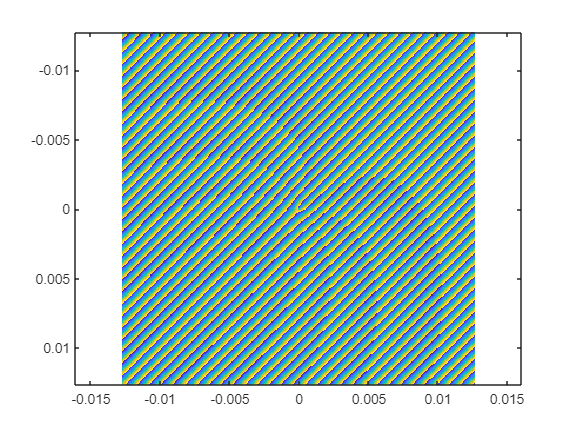


% Visualizacion
imagesc(Xs(1,:),Ys(:,1),angle(U)), axis equal;

## Creación del holograma

La idea es codificar un campo de la forma $U = U_0 \exp(i\phi)$, en un elemento binario.  Esto se puede lograr aplicando la siguiente transformación

$T =\frac{1}{2} + \frac{1}{2}[\text{sign}(\cos A + \cos B)]$,

donde

$A = \text{Arg}(U)$,

$B = \text{sin}^{-1} [U_0/\text{max}(U_0)]$.

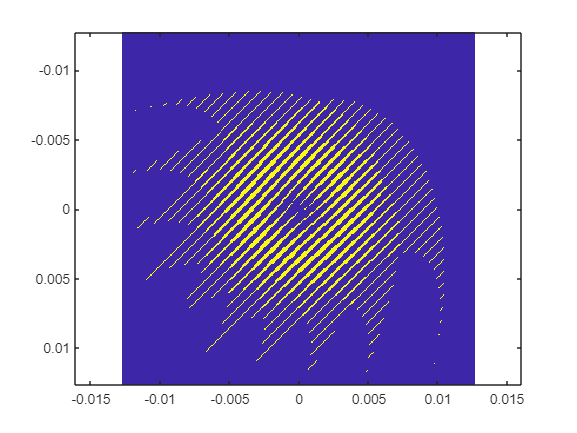

% Parametros del haz
llambd = 633E-9;
w0 = 5E-3;
l = 1;

% \vec{k} = (kx,ky,kz)
gamm = pi/3000;     % angle respect z
thxy = pi/4;        % angle in the xy plane, with respect x axis
k = 2*pi/llambd;
kxy = k*sin(gamm);
kx = kxy*cos(thxy);
ky = kxy*sin(thxy);
LG = @(x,y,w0,phi,ll) ((sqrt(x.^2+y.^2)/w0).^abs(ll)) .* exp((-x.^2 - y.^2)/(w0^2)) .* exp(1i*ll*atan2(y,x));
%V = LG(Xs,Ys,w0,0,l);
V = exp(1i*(kx*Xs + ky*Ys)) .* LG(Xs,Ys,w0,0,l);

% Amplitude
Amp = abs(V);
Amp = Amp/max(Amp(:));

% Phase
Phi = angle(V);
pp = asin(Amp);

%qq = Phi + (kx*Xs + ky*Ys);
qq = Phi;

% Esta es la funcion que nos interesa!
TT01 = 0.5 + 0.5*sign(cos(pp) + cos(qq));
TT10 = 1 - TT01;

% Visualizacion
imagesc(Xs(1,:),Ys(:,1),TT10), axis equal;

## Archivo bmp

Ya tenemos la matriz con lo valores necesario para generar el campo deseado.  Vamos a grabarlo en un archivo.

grabar = 1;
dir = 'C:\Users\jpvin';
archivo = [dir, 'Holobin.bmp'];
if grabar
    imwrite(TT10, archivo)
end

## Recuperación de fase

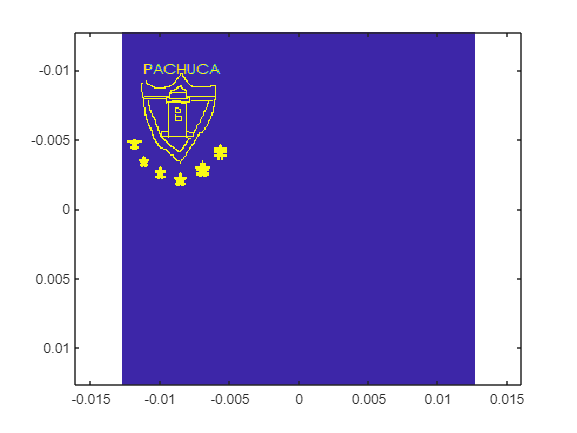

leerarchivo = ['Tuzos.png'];
img = double(rgb2gray(imread(leerarchivo)));
imagesc(Xs(1,:),Ys(:,1),img), axis equal;


A = ifft2(img);
for ii = 1:20
    B = abs(1.0) * exp(1i*angle(A));
    C = fft2(B);
    D = abs(img) .* exp(1i*angle(C));
    A = ifft2(D);
end
Phase = angle(A);

% Visualizacion
imagesc(Xs(1,:),Ys(:,1),Phase), axis equal;

Si tomamos ese elemento de fase, podemos propagarlo y observar su intensidad.

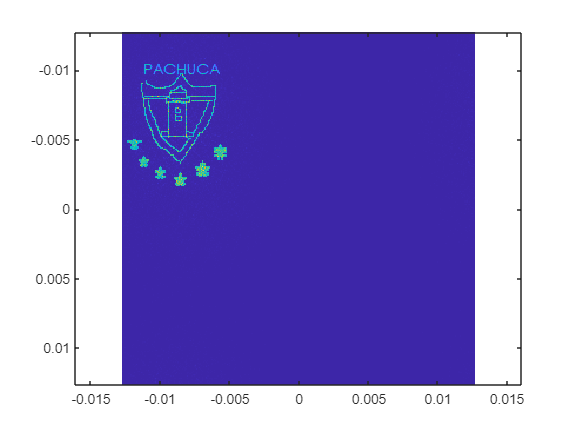

U0 = exp(1i*Phase);
imagesc(Xs(1,:),Ys(:,1),abs(fft2(U0)).^2), axis equal; % fftshift!!!

## Binarización

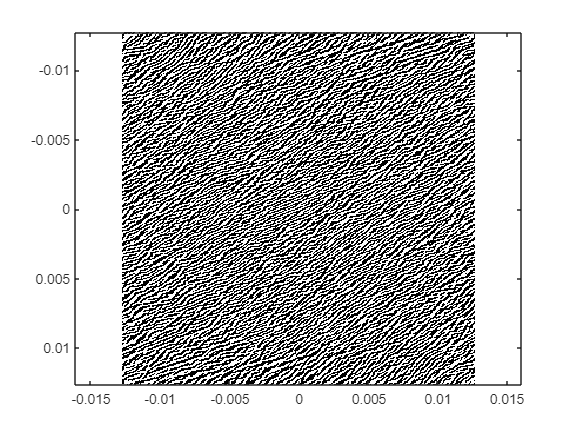


V = 1.0 .* exp(1i*Phase);

% Amplitude
Amp = abs(V);
Amp = Amp/max(Amp(:));

% Phase
Phi = angle(V);
pp = asin(Amp);


qq = Phi;

% Esta es la funcion que nos interesa!
TTgs = 0.5 + 0.5*sign(cos(pp) + cos(qq));

% Visualizacion
imagesc(Xs(1,:),Ys(:,1),TTgs), axis equal; colormap gray


% xlim([-0.0077 0.0073])
% ylim([-0.0032 0.0086])

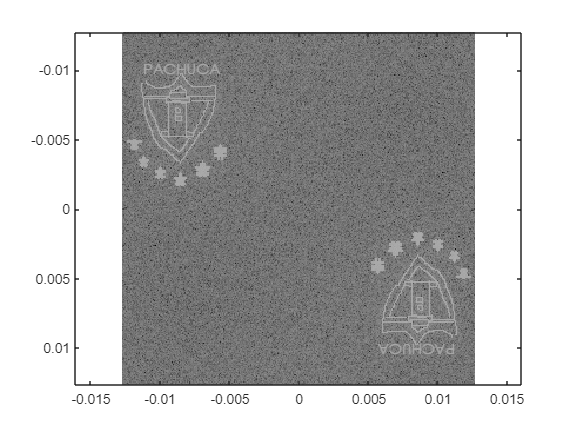

imagesc(Xs(1,:),Ys(:,1),log( abs((fft2(TTgs))).^2 )+1), axis equal;